# **demo07 of Im2mesh package**

demo07 - Demonstrate parameter grad_limit for mesh generation

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-meshes](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-meshes)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function im2mesh use a mesh generator called MESH2D. We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Transition

Let's start demo. Import image Transition.tif.

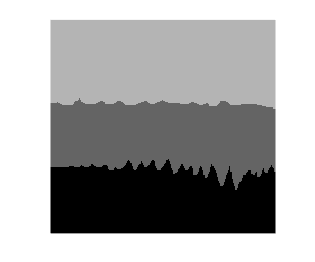

im = imread("Transition.tif");
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

Generate mesh.

opt = [];       % reset opt
opt.threshold_num_turning = 0;
opt.threshold_num_vert_Smo = 0;
opt.threshold_num_vert_Sim = 0;
opt.grad_limit = 0.5;

[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          4                162                288
         10                200                928
         12                203                972


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          5                285                288
         10                297               2061
         20                304               2735
         23                308               2747


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                877               2723
     

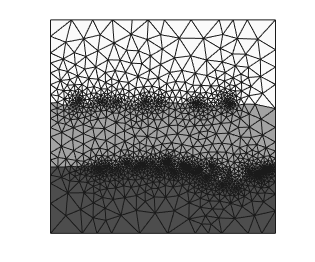

plotMeshes( vert, tria, tnum )

You can see the mesh is very dense in some region. Let's zoom in to take a look.

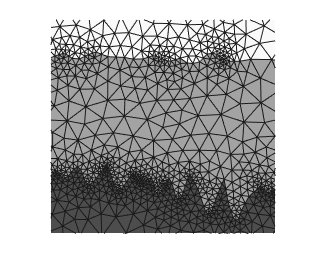

plotMeshes( vert, tria, tnum )

xlim([79 184])
ylim([34 134])

We can evaluate the mesh quality.

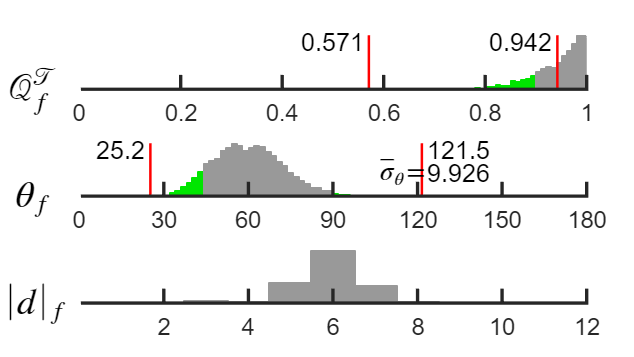

tricost( vert, tria, tnum )

The mean value of Q is 0.942. The minimum Q is 0.571.

## grad_limit

Let's use a smaller grad_limit to see how things are changing.

opt = [];       % reset opt
opt.threshold_num_turning = 0;
opt.threshold_num_vert_Smo = 0;
opt.threshold_num_vert_Sim = 0;
opt.grad_limit = 0.25;

[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          4                162                288
         10                200                928
         12                203                972


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          8                332                288
         10                334               1242
         20                338               4119
         23                338               4137


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4               1259               4107
     

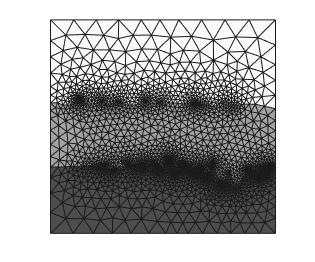

plotMeshes( vert, tria, tnum )

We can evaluate the mesh quality again.

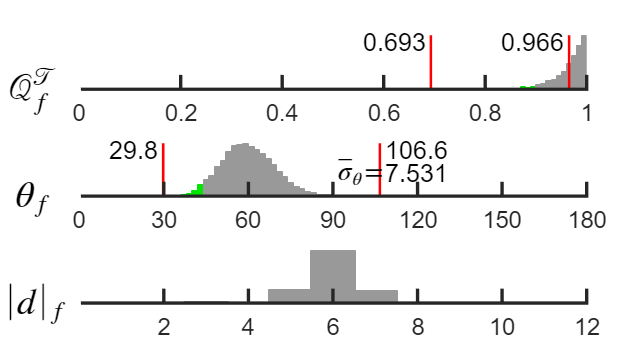

tricost( vert, tria, tnum )

Now, the new Q mean is 0.966. The minimum Q is 0.693. Very good!

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo